# Druga in tretja domača naloga - Iskanje optimalnega kota plovbe

Za kratek uvod bom predstavil problem s čolnom in nato predstavil dve rešitvi - brez uporabe metode (kot je bilo zahtevano pri drugi domači nalogi) ter z uporabo metode (kot je bilo zahtevano pri tretji domači nalogi).

## **Naloga**

Problem je sledeč: s čolnom želimo prečkati reko, tako da začnemo na enem bregu in končamo (hopefully) na nasprotnem. Potovati začnemo z maksimalno možno hitrostjo čolna. Predpostavimo, da celo pot potujemo enakomerno hitro ter da med potjo kota plovbe ne spreminjamo. Zanemarimo vse ostale sile. **Pod katerim kotom moramo navigirati čoln, da prispemo na drugi breg z najmanjšim možnim odmikom od začetne točke relativno glede na breg?**

Skica:

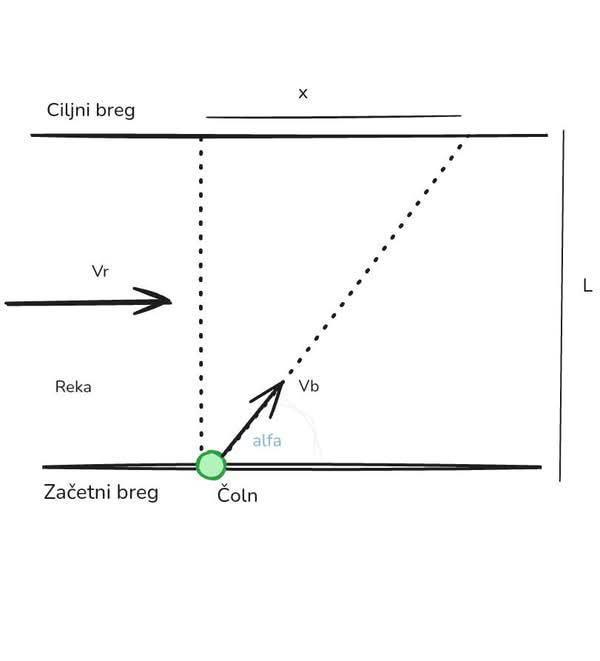

Kjer so spremenljivke naslednje:

- $x$ - premik glede na breg

- $L$ - širina reke

- $V_r$ - hitrost toka reke

- $V_B$ - hitrost čolna

- $\alpha$ ("alpha") - kot, pod katerim navigiramo čoln

Funkcija za premik je odvisna od kota $\alpha$ in razmerja med hitrostima $\eta = V_r / V_b$.

#### 
$$x(\alpha, \eta) = \frac{\cos(\alpha) + \eta}{\sin(\alpha)}$$


Najmanjši premik najdemo preko minimuma te funkcije. $\eta$ vrednosti poznamo, zato lahko predpostavljamo, da je $\eta = const.$ in odvajamo funkcijo po $\alpha$. Dobimo odvod:

#### 
$$x'(\alpha) = \frac{-1-\eta \cos(\alpha)}{\sin(\alpha)}$$


Iščemo kot v intervalu $(0,\pi)$, saj:

- če je kot 0°, potuje čoln v isto smer kot reka in nikoli ne pride do nasprotnega brega, saj je v tem primeru $y-$komponenta hitrost $V_B$ enaka 0 ($V_B \sin(0) = V_B \cdot 0 = 0$). Podobno lahko vidimo, da $\alpha$ nikoli ne sme biti enak 0, saj $\sin(0)=0$ in deljnje z 0 ni definirano.

- podobno čoln ne potuje proti nasprotnem bregu, če je koti enak 180° oziroma $\pi$, saj je $\sin(\pi) = 0$ ; enaki argumenti kot zgoraj.

## Brez uporabe newtonove metode (HW2)

#### *a) Find optimal angles for *$\eta = 1.5, 2.0, 2.5, 3.0$*.*

Rešimo enačbo $x'(\alpha) = 0$ za vsako $\eta$ vrednost, da dobimo optimalni kot. Definiramo funkcijo za premik.

clear all;
syms x(a, e)
x(a, e) = (e + cos(a)) ./ sin(a);

Definiramo $\eta$ vrednosti in inicializiramo polje, ki bo hranilo optimalne kote.

e_vals = [1.5, 2.0, 2.5, 3.0];
n = length(e_vals);
opt_a = zeros(n, 1);

Gremo čez vsako $\eta$ vrednost, jo vstavimo v funkcijo, dobimo odvod funkcije po $\alpha$ in rešimo enačbo $x'(\alpha)=0$, da dobimo možne rešitve. Prava rešitev bo v intervalu $(0,\pi)$. Ker dobimo vrednost v radianih, jo na koncu še pretvorimo v stopinje.

for i=1:n
    xe = subs(x, e, e_vals(i));
    dx = diff(xe, a);
    s = solve(dx == 0);
    sol = eval(s);
    opt = sol(sol > 0 & sol < pi);
    opt_a(i) = rad2deg(opt);
end

Rešitve:

for i = 1:n
    if (i == 1)
        fprintf("eta    optimal angle\n---    -------------");
    end
    fprintf("%.2f   %i\n", e_vals(i), opt_a(i));
end

eta    optimal angle
---    -------------

1.50   1.318103e+02
2.00   1.200000e+02
2.50   1.135782e+02
3.00   1.094712e+02


#### *c) Plot four functions on the same plot, for*$\eta=1.5$*, *$2.0$*, *$2.5$* and *$3.0$*.*

Ustvarimo seznam $x$-vrednosti z `linspace,` ki jih enakomerno razporedi. V bistvu naredimo interval $(0,\pi)$.

alpha_vals = linspace(0.1, pi-0.1);
alpha_deg = rad2deg(alpha_vals);

Vsako iteracijo vstavimo v funckijo $\eta$ vrednost in celoten interval `alpha_vals` in prikažemo graf.

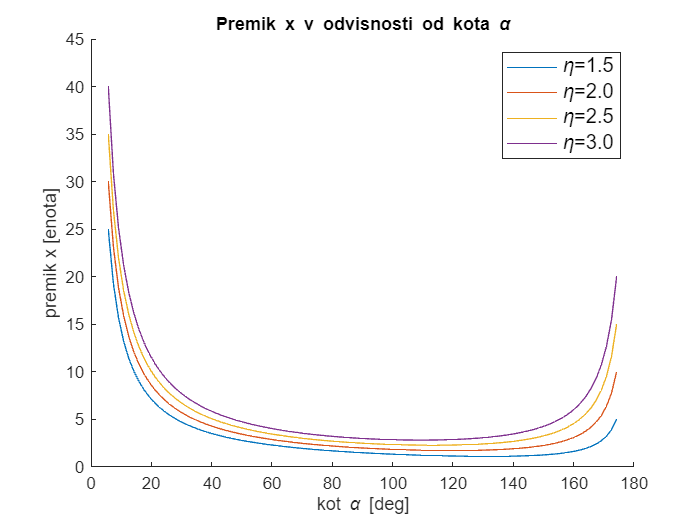

figure
for i = 1:n
    sol = subs(x, e, e_vals(i));
    sol = eval(subs(sol, a, alpha_vals));
    hold on
    plot(alpha_deg, sol);
end
hold off

title('Premik x v odvisnosti od kota \alpha')
legend('\eta=1.5','\eta=2.0', '\eta=2.5', '\eta=3.0',  'FontSize', 12);
ylabel('premik x [enota]');
xlabel('kot \alpha [deg]');

#### *d) Calculate distance *$d$* (displacement from the origin *$x_0$*) for *$\eta = 2$* and optimal angle *$\alpha = 120$.

Vrednosti vstavimo v funkcijo in izračunamo rezultat (kot najprej pretvorimo v radiane).

sol = eval(subs(x, {e, a}, {2, deg2rad(120)}));
fprintf("Displacement for eta = 2 and alpha = 120: %d\n", sol);

Displacement for eta = 2 and alpha = 120: 1.732051e+00


## Uporaba Newtonove metode za aproksimiranje optimalnega kota plovbe (HW3)

#### *a) Plot two functions on the same graph for η=0.1 and η=1.1*

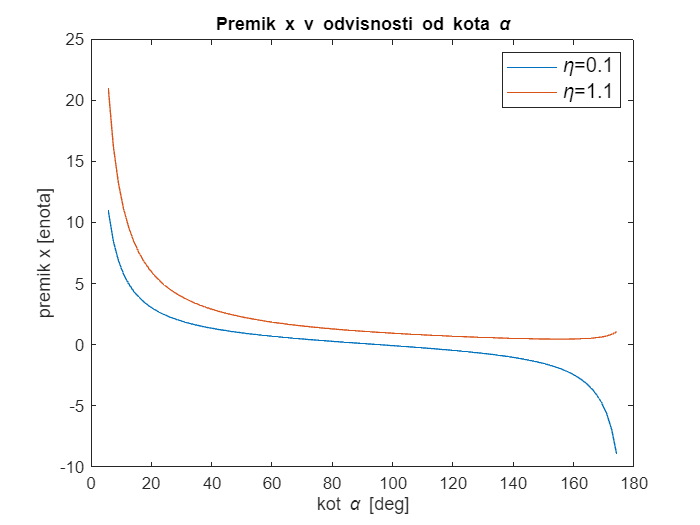

figure
plot(alpha_deg, eval(subs(x, {e, a}, {0.1, alpha_vals})))
hold on
plot(alpha_deg, eval(subs(x, {e, a}, {1.1, alpha_vals})))
hold off

title('Premik x v odvisnosti od kota \alpha')
legend('\eta=0.1', '\eta=1.1',  'FontSize', 12);
ylabel('premik x [enota]');

xlabel('kot \alpha [deg]');

#### *b) Write a Matlab script (step-by-step) that finds the roots of a function using the Newton method. Use your Matlab script (Newton method) and find optimal steering angle for η=0.1, 0.2, 0.3, 0.4, 0.5,  0.6, 0.7, 0.8 and 0.9.*

Z Newtonovo metodo lahko aproksimiramo ničle funkcije s pomočjo tangente na graf funkcije v neki točki $x$. 

Začnemo z *initial guess, *ki naj bi bil najboljši trenutni približek ničle (ali pa pač naključna vrednost). Naj bo ta vrednost označena z $x_0$. Izračunamo nov približek ničle s pomočjo enačbe za tangento, ki jo dobimo s pomočjo odvoda funkcije. Naj bo nova vrednost označena z $x_1$. Preverimo, ali je $f(x_1) = 0$. Če je, imamo našo vrednost za ničlo. V večini primerov pa bodo vrednosti le konvergirale proti 0, nikoli pa je ne bodo zadele, zato poračunamo razliko med $x_0$ in $x_1$ in preverimo, če je razlika manjša od tolerance (npr. toleranca oz. razlika 0.01 pomeni, da imata skupno eno decimalno mesto). Če je, vzamemo vrednost $x_1$ kot naš približek, sicer nadaljujemo z iskanjem, tako da bo $x_1$ novi *initial guess.*

Enačba za $x_n
$ je naslednja:

#### 
$$x_{n+1}= x_n - \frac{f(x_n)}{f'(x_n)}$$


Za naš primer je malo drugače - spremeni se le zadnji člen enačbe, saj ne aproksimiramo ničle, ampak minimum, toda metoda deluje po istem principu; iščemo točko, kjer bo  $f'(x_1)=0$ (namesto $f(x_1)=0$). Nova enačba:

#### 
$$x_{n+1} = x_n - \frac{f'(x_n)}{f''(x_n)}$$


Initial guess postavimo na sredino intervala $(0, \pi)$ in toleranco na vsaj 3 enake decimalke. Definiramo seznam $\eta$ vrednosti in seznam za optimalne vrednosti kota.

init = pi/2;
tol = 1e-4;
newton_e_vals = 0.1 : 0.1 : 0.9;
m = length(e_vals);
newton_opt_a = zeros(m, 1);

Za ta primer bom *hard-codal *odvoda funkcije, saj je pristop s simboličnimi izrazi ter `eval(subs...` trajal predolgo ter ni pravilno izračunalo odvoda. Nič zato, saj je funkcija preprosta in odvoda ni težko izračunati. Ustvarimo torej 2 *function handles *za prvi in drugi odvod.

dx = @(a, e) (e + cos(a)) ./ sin(a);
ddx = @(a, e) (-1 - e .* cos(a)) ./ sin(a).^2;

**Zunanja zanka:** Zapeljemo se čez vsako $\eta$ vrednost. Vsako iteracijo ponastavimo *initial guess *na vrednost `init` in začnemo z aproksimiranjem.

**Notranja zanka: **novo vrednost `xn` izračunamo z enačbo predstavljeno zgoraj, tako da izračunamo odvoda v točki `x0`. Preverimo toleranco in nadaljuemo, če ni presežena, drugače shranimo izračunan približek v `newton_opt_a`.

for i = 1:m
    x0 = init;
    
    while true
        xn = x0 - dx(x0, newton_e_vals(i)) / ddx(x0, newton_e_vals(i));
        if (abs(xn - x0) <= tol)
            newton_opt_a(i) = rad2deg(xn);
            break
        end
        x0 = xn;
    end
end

Rešitve:

for i = 1:m
    if (i == 1)
        fprintf("eta    optimal angle\n---    -------------");
    end
    fprintf("%.2f   %i\n", newton_e_vals(i), newton_opt_a(i));
end

eta    optimal angle
---    -------------

0.10   9.573917e+01
0.20   1.015370e+02
0.30   1.074576e+02
0.40   1.135782e+02
